convolution (Finite*Finite)

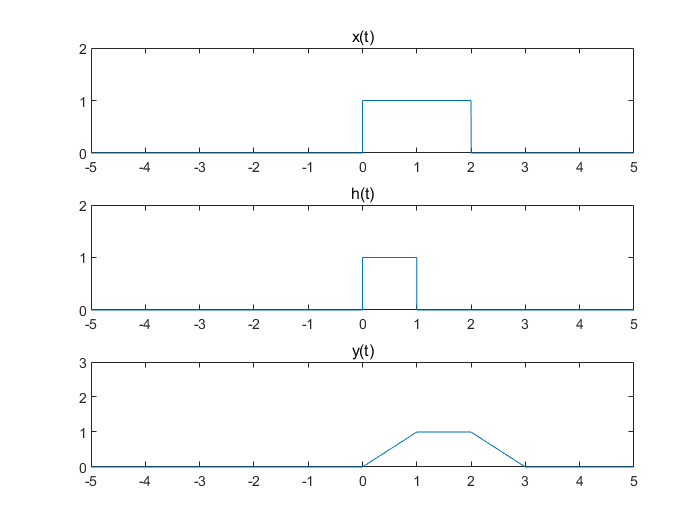

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


step=0.001;
t=-5:step:5; 
x=stepfun(t,0)-stepfun(t,2); % x(t)=u(t+2)-u(t-2)
h=stepfun(t,0)-stepfun(t,1); % h(t)=u(t+1)-u(t-1)
y=conv(x,h)*step; % 컨벌루션 수행 
convolution_size=length(x)-1; convolution_temp=(length(y)-1)/2;
convolution_size=[convolution_temp-convolution_size/2+1 convolution_temp+convolution_size/2+1];
subplot(3,1,1); plot(t,x); 
title('x(t)'); axis([-5 5 0 2]); 
subplot(3,1,2); plot(t,h); 
title('h(t)'); axis([-5 5 0 2]); 
subplot(3,1,3); plot(t,y(convolution_size(1):convolution_size(2)))
title('y(t)'); axis([-5 5 0 3]);

convolution (Finite*Infinite)

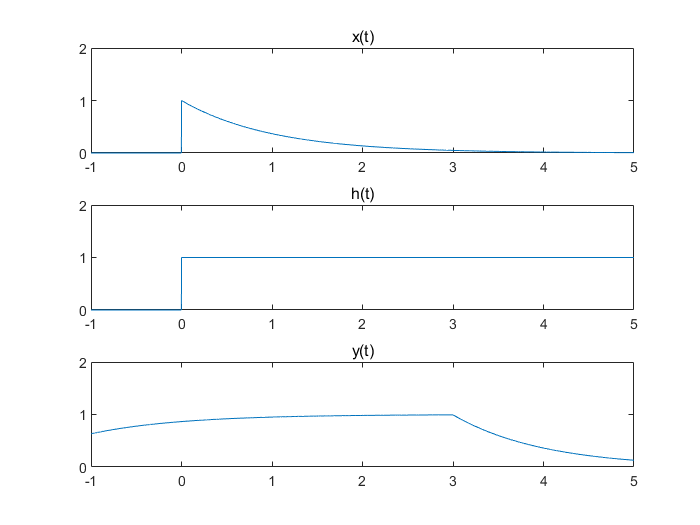

step=0.001;
t=-1:step:5;
x=exp(-t).*stepfun(t,0);
h=stepfun(t,0);
y=conv(x,h)*step;
convolution_size=length(x)-1; convolution_temp=(length(y)-1)/2;
convolution_size=[convolution_temp-convolution_size/2+1 convolution_temp+convolution_size/2+1];
subplot(3,1,1); plot(t,x);
title('x(t)'); axis([-1 5 0 2]);
subplot(3,1,2); plot(t,h);
title('h(t)'); axis([-1 5 0 2]);
subplot(3,1,3); 
plot(t,y(convolution_size(1):convolution_size(2)))
title('y(t)'); axis([-1 5 0 2]);

convolution_size(1)

ans = 3001

convolution_size(2)

ans = 9001

x

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


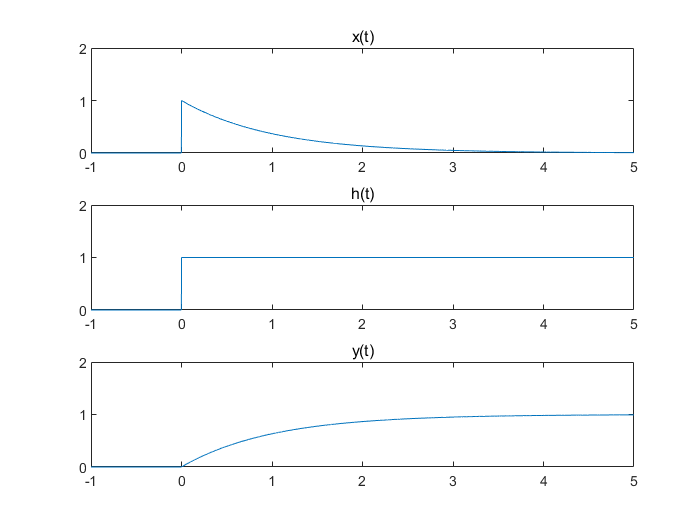

close all; clear all; clc;
t=-1:0.001:5; % 시간축 설정(-1에서 5까지 0.001 간격)
x=exp(-t).*stepfun(t,0); % x(t)=exp(-t)u(t) 생성
h=stepfun(t,0); % h(t)=u(t) 생성
y=conv(x,h)*0.001; % 컨벌루션 수행 y(t)=x(t)*h(t)
convolution_size=length(x)-1; convolution_temp=(length(y)-1)/2;
convolution_size=[convolution_temp-convolution_size/2+1 convolution_temp+convolution_size/2+1];
subplot(3,1,1); plot(t,x); % 3행 1열 분할 그림 창의 1번 창
title('x(t)'); % x(t)의 그림 제목
axis([-1 5 0 2]); % x축과 y축의 그림 영역 지정
subplot(3,1,2); plot(t,h); % 3행 1열 분할 그림 창의 3번 창
title('h(t)'); % h(t)의 그림 제목
axis([-1 5 0 2]); % x축과 y축의 그림 영역 지정
subplot(3,1,3); plot(t,y(1001:7001)) % 3행 1열 분할 그림 창의 5번 창
title('y(t)'); % y(t)의 그림 제목
axis([-1 5 0 2]); % x축과 y축의 그림 영역 지정

x

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
